# **一、 核心概念：什么是 Butterworth？它与低通的关系**

### ***1.低通滤波器与巴特沃斯的关系***

**低通 (Low-Pass)** ：滤波器功能

- 低频信号通过，高频信号被阻断。

**巴特沃斯(Butterworth)** ：滤波器的数学实现

- 巴特沃斯不是低通滤波器的同义词，它是**一种特殊的逼近函数**。

- 你可以设计“巴特沃斯低通”、“巴特沃斯高通”，甚至“巴特沃斯带通”。

- 除了巴特沃斯，实现低通功能的还有**切比雪夫 (Chebyshev)**（允许波纹，但在截止频率处切得更狠）和**贝塞尔 (Bessel)**（强调相位线性，群延时一致）。

### ***2.为什么机器人控制偏爱巴特沃斯？***

因为它的通带最大平坦特性 (Maximally Flat)。

在机器人控制中，传感器读回来的数（比如角度$ $10^\circ$$），我们希望在滤波后，只要是低频真实信号，它依然是严格的$ $10.5^\circ$$，而不是变成$ $10.5^\circ$ 或 $9.5^\circ$$（切比雪夫滤波器就会有这种波纹）。巴特沃斯保证了保真度。

# **二、 数学原理：从幅频响应到 S 平面**

### ***1. 幅频响应 (Magnitude Response)：即能量增益与频率的关系***

1930年，Stephen Butterworth 提出了这个经典公式。对于一个 $n$ 阶低通滤波器，其幅值平方为：


$$ |H(j\omega)|^2 = \frac{1}{1 + (\frac{\omega}{\omega_c})^{2n}} $$


- $\omega$：信号频率

- $\omega_c$：截止频率 (-3dB 点)

- $n$：滤波器的阶数

**观察上式，我们可以发现：**

- 当$ $\omega \ll \omega_c$$（通带）：分母$ $\approx 1$$，增益 $$\approx 1$$（非常平坦）。

- 当$ $\omega = \omega_c$$（截止点）：分母 $$= 2$$，增益$ $= \frac{1}{\sqrt{2}} \approx 0.707$$ (即 -3dB)。

- 当$ $\omega \gg \omega_c$$（阻带）：分母迅速增大，增益迅速衰减为 0。

**低频分量可以有效通过这个滤波器，而高频分量则被有效抑制**

### ***2.从频域反推传递函数***

利用关系式$ $s = j\omega \Rightarrow \omega = s/j$$，我们有：$$$|H(j\omega)|^2 = H(j\omega) \cdot H(-j\omega)$$$将其拓展到$ $s$ $平面：


$$$$H(s)H(-s) = \frac{1}{1 + (\frac{s}{j\omega_c})^{2n}}$$$$


为了找到$ $H(s)$ $的极点，我们要让分母为 0：


$$$$1 + (-1)^n (\frac{s}{\omega_c})^{2n} = 0$$$$


解这个方程，我们可以发现极点$ $s_k$ $分布在一个**半径为**$ $\omega_c$$** 的圆**上：


$$ s_k = \omega_c \cdot e^{j \frac{\pi(2k + n - 1)}{2n}} \quad k = 1, 2, ..., 2n $$


为了保证系统稳定，我们只选取 $s$ 平面**左半部分 (LHP)** 的 $n$ 个极点。

### ***3.极点分布可视化与物理意义***

让我们通过代码直观地看一看，随着阶数 n 的增加，极点是如何排列成一个圆的。

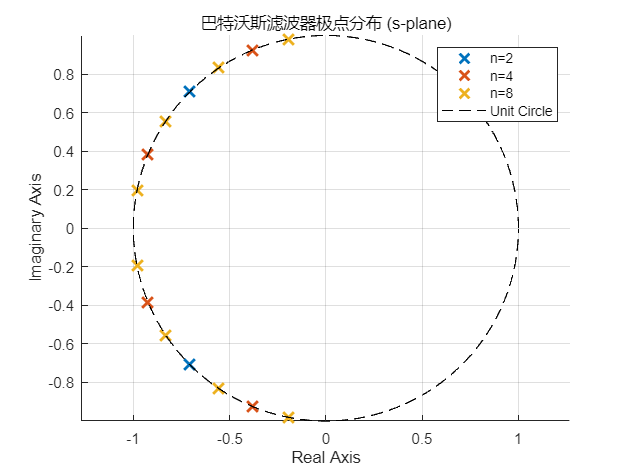

wc = 1; % 假设截止频率为 1 rad/s
figure; hold on; grid on; axis equal;
colors = ['r', 'g', 'b'];
orders = [2, 4, 8]; % 观察 2阶, 4阶, 8阶

for i = 1:length(orders)
    n = orders(i);
    [z, p, k] = butter(n, wc, 's'); % 's' 表示设计模拟滤波器
    plot(real(p), imag(p), 'x', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', ['n=' num2str(n)]);
end

% 画出单位圆作为参考
theta = 0:0.01:2*pi;
plot(cos(theta), sin(theta), 'k--', 'DisplayName', 'Unit Circle');

xlabel('Real Axis'); ylabel('Imaginary Axis');
title('巴特沃斯滤波器极点分布 (s-plane)');
legend show;
hold off;

**极点位置的物理意义解析：**

- 圆的半径 ($\omega_n$)：代表滤波器的***带宽*** (Bandwidth)。半径越大，截止频率越高，系统反应越快，但对高频噪声抑制能力变差

- 实部距离 ($\sigma$)：代表信号的***衰减速度***。极点离虚轴越远（越靠左），瞬态响应消失得越快（收敛快，对外界不敏感）

- 角度 ($\theta$)：代表***阻尼比*** ($\zeta$) 。极点越靠近虚轴（角度接近 $90^\circ$），阻尼比越小，系统震荡越剧烈（对外界敏感）

巴特沃斯的设计精髓在于：它把极点均匀排布在圆上，从而在响应速度和平稳性之间达成了一种优雅的数学平衡。

# **三、 经典案例：二阶巴特沃斯滤波器**

### ***1.S域分析***

根据公式，极点间隔$ $90^\circ$ ($\pi/2$)$，且关于实轴对称，落在左半平面。角度分别为$ $135^\circ$ 和 $225^\circ$ (即 $-135^\circ$)$。


$$$$s_{1,2} = \omega_c (\cos 135^\circ \pm j \sin 135^\circ) = \omega_c (-\frac{\sqrt{2}}{2} \pm j \frac{\sqrt{2}}{2})$$$$


这是控制中最常见的情况 ($n=2$)。 极点角度分别为 $135^\circ$ 和 $225^\circ$。

其传递函数形式为：


$$ H(s) = \frac{\omega_c^2}{s^2 + \sqrt{2}\omega_c s + \omega_c^2} $$


分子之所以是$ $\omega_c^2$
$，仅仅是为了**抵消分母中的常数项**，从而保证在频率为 0 时，分母和分子相等，增益为 1。可以看出标准的巴特沃斯滤波器低通滤波器是**全极点滤波器 (All-pole filter)**

回忆《自动控制原理》中的标准二阶系统：


$$ G(s) = \frac{\omega_n^2}{s^2 + 2\zeta\omega_n s + \omega_n^2} $$


核心结论： 二阶巴特沃斯滤波器的阻尼比为：


$$ \zeta = \frac{\sqrt{2}}{2} \approx 0.707 $$


在控制工程中，$$\zeta = 0.707$$ 被称为**工程最佳阻尼比**。这意味着它在阶跃响应中， 既没有过大的超调（约 4%），又能最快地达到稳态。这就是为什么巴特沃斯滤波器在物理上表现为：**把噪声滤得很干净，且对原始信号的动态性能破坏最小**

### ***2.阶跃响应验证与Bode图***

我们来验证一下 0.707 阻尼比的特性。我们将对比巴特沃斯滤波器和切比雪夫滤波器对阶跃信号的响应。

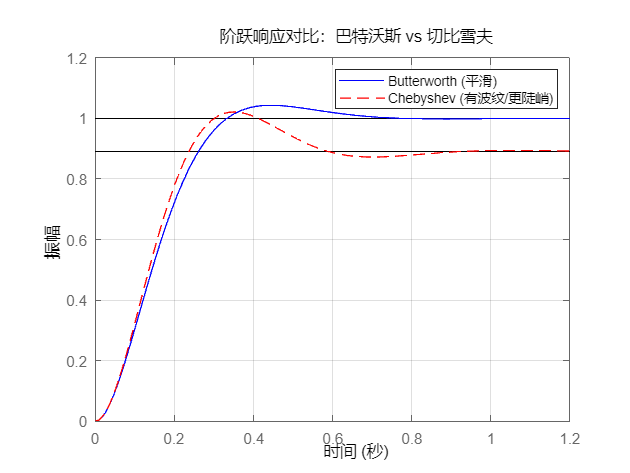

wc = 10; % 截止频率 10 rad/s

% 设计二阶巴特沃斯
[num_b, den_b] = butter(2, wc, 's');
sys_butter = tf(num_b, den_b);

% 设计二阶切比雪夫 (允许 1dB 波纹)
[num_c, den_c] = cheby1(2, 1, wc, 's');
sys_cheby = tf(num_c, den_c);

% 绘图对比
figure;
step(sys_butter, 'b', sys_cheby, 'r--');
legend('Butterworth (平滑)', 'Chebyshev (有波纹/更陡峭)');
title('阶跃响应对比：巴特沃斯 vs 切比雪夫');
grid on;    

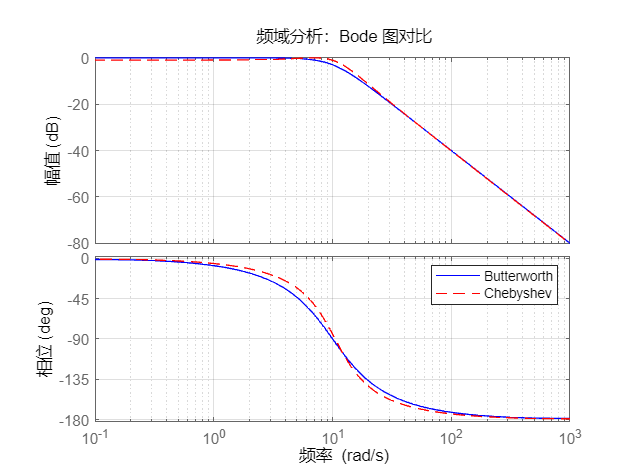


figure;
bode(sys_butter, 'b', sys_cheby, 'r--');
grid on;
legend('Butterworth', 'Chebyshev');
title('频域分析：Bode 图对比');

### ***3.巴特沃斯滤波器的阶数***

*阶数越高，滤波越干净，但信号迟到越久*

每增加 1 个阶数（增加 1 个极点），高频信号的衰减速度增加 -20dB/dec（即频率每翻10倍，噪声能量多衰减100倍）。

- **2阶**：-40dB/dec（噪声衰减 100倍）

- **10阶**：-200dB/dec（噪声衰减 10,000,000,000倍）

但是这也在时域上带来了滞后，每一个极点，最大会贡献$ $-90^\circ$ $的相位滞后。

- 1阶：滞后$ $90^\circ$$。

- 2阶：滞后$ $180^\circ$$（反相）

- 10阶：滞后 $$900^\circ$$

在物理世界里，每一个极点通常对应一个**独立的能量存储元件**（电容、电感、弹簧、质量块）。**在巴特沃斯滤波器中**，这 N 个极点不是简单地串联（那样效果不好），而是通过数学上的精心排列（都在圆上），让它们互相配合，达成“合力最大化”。

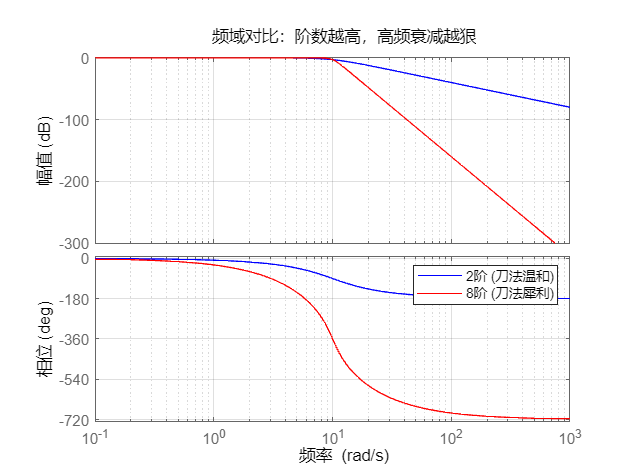

% 我们对比 2阶 (Low Order) 和 8阶 (High Order) 巴特沃斯滤波器的表现。

wc = 10; % 截止频率 10 rad/s

% 1. 设计滤波器
[num2, den2] = butter(2, wc, 's');
sys2 = tf(num2, den2);

[num8, den8] = butter(8, wc, 's');
sys8 = tf(num8, den8);

% 2. 频域对比 (Bode 图) - 看“屠龙刀”的效果
figure;
bode(sys2, 'b', sys8, 'r');
grid on;
legend('2阶 (刀法温和)', '8阶 (刀法犀利)');
title('频域对比：阶数越高，高频衰减越狠');

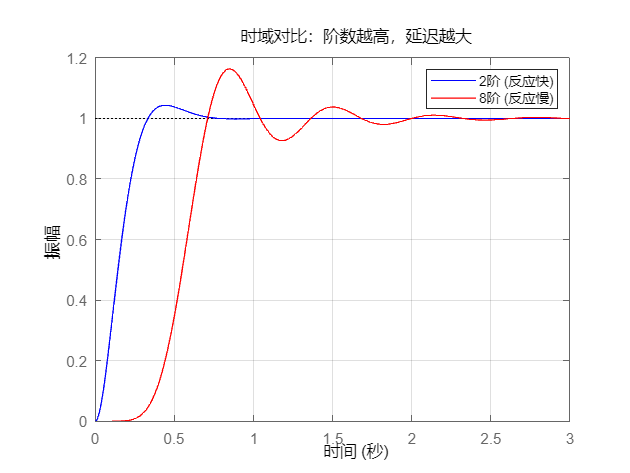

% 注意看 Magnitude 图：红色线在高频部分垂直下降，像悬崖一样。
% 注意看 Phase 图：红色线的相位滞后极其严重（往下掉得深）。

% 3. 时域对比 (Step Response) - 看“延迟”的代价
figure;
step(sys2, 'b', sys8, 'r');
grid on;
legend('2阶 (反应快)', '8阶 (反应慢)');
title('时域对比：阶数越高，延迟越大');

% 观察：
% 蓝色线 (2阶)：迅速上升，稍微有点超调，很快稳定。
% 红色线 (8阶)：前面有一段平的（死区时间），信号好像“愣”了一会儿才反应过来，上升较慢。

### ***4.特性对比***

- 巴特沃斯 (Butterworth)： 通带最平坦 (无波纹)，阻尼比 0.707 (二阶时)，瞬态响应好。 **应用**：控制反馈回路、音频处理。

- 切比雪夫 (Chebyshev)： 通带或阻带有波纹，幅频特性下降得更陡峭（滤除非线性更强）。**应用**：只关心频率分离，不关心波形失真的场景。

- 贝塞尔 (Bessel)： * 群延时最平坦（线性相位）。**应用**：高速通信、脉冲信号处理。

# **四、数字化实现**

理解了模拟原理 $H(s)$ 后，在机器人单片机中，我们需要将其转化为差分方程。 常用的方法是双线性变换 (Bilinear Transform)。 我们的任务是：将连续传递函数 $H(s)$ 转换为离散传递函数 $H(z)$，最终推导出差分方程。

### ***1. 核心工具：双线性变换 (Bilinear Transform / Tustin's Method)***

在控制工程中，最常用的离散化方法是 ***Tustin 变换***。

**原理**：利用梯形公式来近似积分。 **数学代换**：


$$ s = \frac{2}{T_s} \frac{1 - z^{-1}}{1 + z^{-1}} $$


- $T_s$：采样时间 (Sampling Time)。

- $z^{-1}$：代表“延迟一拍”，即上一次的数据。

**为什么要用 Tustin？** 相比于简单的欧拉法，Tustin 变换能更好地保持系统的稳定性，且会将左半平面的极点精确映射到单位圆内。

### *2. MATLAB 实战：将二阶巴特沃斯离散化*

假设我们要设计一个截止频率为 10Hz 的滤波器，系统采样频率为 1000Hz。

% --- 步骤 A: 定义模拟系统 ---
Fc = 10;                % 截止频率 10Hz
Wc = 2 * pi * Fc;       % 转化为角频率 (rad/s)
[b_s, a_s] = butter(2, Wc, 's'); % 得到模拟系数
sys_analog = tf(b_s, a_s);

% --- 步骤 B: 定义采样时间 ---
Fs = 1000;              % 采样频率 1000Hz (机器人控制常用)
Ts = 1 / Fs;            % 采样周期 0.001s

% --- 步骤 C: 进行 c2d (Continuous to Discrete) 转换 ---
% 使用 'tustin' 方法
sys_digital = c2d(sys_analog, Ts, 'tustin');

% 显示离散传递函数
disp('离散传递函数 H(z):');

离散传递函数 H(z):


disp(sys_digital);

  tf - 属性:

       Numerator: {[9.4408e-04 0.0019 9.4408e-04]}
     Denominator: {[1 -1.9112 0.9150]}
        Variable: 'z'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 1.0000e-03
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



### *3. 验证：模拟 vs 数字*

我们必须确认离散化后的系统行为是否和原来的模拟系统一致。 重点观察：数字系统会有轻微的延迟，但在低频段应完美重合。

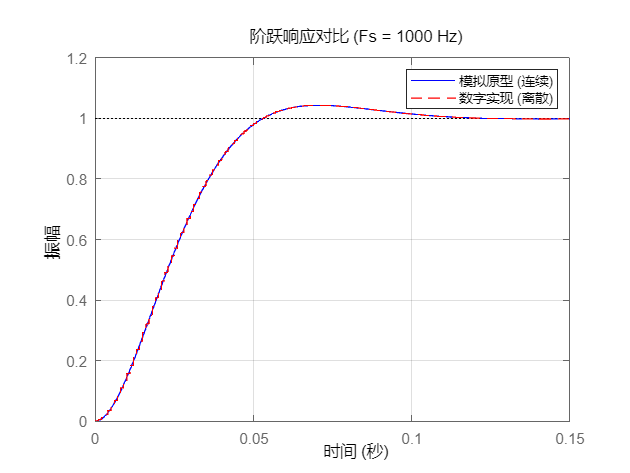

figure;
step(sys_analog, 'b', sys_digital, 'r--');
legend('模拟原型 (连续)', '数字实现 (离散)');
title(['阶跃响应对比 (Fs = ' num2str(Fs) ' Hz)']);
grid on;

% 尝试把上面的 Fs 改成 50Hz (只比 10Hz 快5倍)，你会发现红色线开始走样了。
% 这就是为什么采样频率通常要是带宽的 10-20 倍以上。

### *4. 终极目标：推导差分方程 (Difference Equation)*

单片机看不懂 H(z)，它需要的是类似 y = a*x + b*y_old 的代码。

离散传递函数的通用形式为：


$$ H(z) = \frac{Y(z)}{X(z)} = \frac{b_0 + b_1 z^{-1} + b_2 z^{-2}}{1 + a_1 z^{-1} + a_2 z^{-2}} $$


- $Y(z)$：输出（滤波后的值）

- $X(z)$：输入（传感器原始读数）

交叉相乘展开： 


$$$ Y(z) (1 + a_1 z^{-1} + a_2 z^{-2}) = X(z) (b_0 + b_1 z^{-1} + b_2 z^{-2}) $$$


转换回时域 ($z^{-k}$ 意味着 $y[n-k]$)： 


$$$ y[n] + a_1 y[n-1] + a_2 y[n-2] = b_0 x[n] + b_1 x[n-1] + b_2 x[n-2] $$$


移项得到最终的可编程公式：


$$ y[n] = b_0 x[n] + b_1 x[n-1] + b_2 x[n-2] - a_1 y[n-1] - a_2 y[n-2] $$


### ***5. C 语言代码实现***

`/* ===================================================================`

` * 模块名称: Dynamic Butterworth Filter (2nd Order)`

` * 功能: 支持在单片机运行过程中动态修改截止频率 (Fc) 和采样率 (Fs)`

` * 依赖: <math.h> (需要 tanf, sqrtf)`

` * =================================================================== */`

`#include <math.h>`

`// 兼容性定义：防止部分编译器缺少 M_PI`

`#ifndef M_PI`

`#define M_PI 3.14159265358979323846f`

`#endif`

`// [1] 滤波器对象结构体`

`typedef struct {`

`    // --- 系数 (由 Init 函数自动计算) ---`

`    float b0, b1, b2;`

`    float a1, a2;`

`    // --- 历史状态 (用于差分方程) ---`

`    float x1, x2; // 输入的历史 (x[n-1], x[n-2])`

`    float y1, y2; // 输出的历史 (y[n-1], y[n-2])`

`} Butter2nd;`

`// [2] 初始化/重置函数`

`// 功能: 根据 Fc 和 Fs 计算二阶巴特沃斯系数 (使用双线性变换+预畸变)`

`void butter2nd_init(Butter2nd *filter, float fc_hz, float fs_hz) {`

`    // 安全检查: 截止频率不得超过采样率的一半`

`    if (fc_hz >= fs_hz / 2.0f) {`

`        fc_hz = fs_hz * 0.45f; // 强制限制为 0.45 倍作为保护`

`    }`

`    // --- 核心算法: 预畸变双线性变换 ---`

`    // 1. 计算 lambda = 1 / tan(pi * fc / fs)`

`    float lambda = 1.0f / tanf(M_PI * fc_hz / fs_hz);`

`    // 2. 计算分母公共项 D = lambda^2 + sqrt(2)*lambda + 1`

`    float sqrt2 = 1.41421356f;`

`    float D = (lambda * lambda) + (sqrt2 * lambda) + 1.0f;`

`    // 3. 计算离散系数`

`    filter->b0 = 1.0f / D;`

`    filter->b1 = 2.0f * filter->b0;`

`    filter->b2 = filter->b0;`

`    filter->a1 = 2.0f * (1.0f - lambda * lambda) / D;`

`    filter->a2 = (1.0f - sqrt2 * lambda + lambda * lambda) / D;`

`    // 4. 清空历史状态 (防止参数突变导致输出跳变)`

`    filter->x1 = 0.0f; filter->x2 = 0.0f;`

`    filter->y1 = 0.0f; filter->y2 = 0.0f;`

`}`

`// [3] 实时滤波函数 (放入定时器中断或控制环路)`

`float butter2nd_apply(Butter2nd *filter, float input) {`

`    // 差分方程: y[n] = b0*x + b1*x1 + ... - a1*y1 - ...`

`    float output = filter->b0 * input `

`                 + filter->b1 * filter->x1 `

`                 + filter->b2 * filter->x2 `

`                 - filter->a1 * filter->y1 `

`                 - filter->a2 * filter->y2;`

`    // 更新历史状态 (移位)`

`    filter->x2 = filter->x1;`

`    filter->x1 = input;`

`    filter->y2 = filter->y1;`

`    filter->y1 = output;`

`    return output;`

`}`

***笔者：卢俊烨***

#### ***日期：2025.12.02***

***https://github.com/yagami-light7***